% Solve for the coefficients of the CCM.
% We use monochrome and RGB values from 3 patches on a color chart.
% This gives us 3 matrices each with 3 unknowns and 3 equations to solve
% for all 9 coefficients in the CCM.
% Each equation is of the form Sc=b.
diary colorCorrectionLog
S_grayscaleMatrix = [
    80 80 80;
    112 112 112;
    66 66 66;
    ]

S_grayscaleMatrix =     80    80    80
   112   112   112
    66    66    66


% S_grayscaleMatrix = [
%     80 0 0;
%     0 112 0;
%     0 0 66;
%     ]

b_redMatrix = [166 65 51]';
b_greenMatrix = [41 145 58]';
b_blueMatrix = [56 65 144]';

c_redMatrix = S_grayscaleMatrix\b_redMatrix

c_redMatrix =    NaN
   NaN
   Inf


c_greenMatrix = S_grayscaleMatrix\b_greenMatrix

c_greenMatrix =    NaN
   NaN
  -Inf


c_blueMatrix = S_grayscaleMatrix\b_blueMatrix

c_blueMatrix =    NaN
   NaN
   Inf



%transformImage(c_redMatrix, c_greenMatrix, c_blueMatrix)

% Show augmented matrix in rref. Visual verification if it is singular.
S_grayscaleMatrix(:,4) = b_redMatrix;
R = rref(S_grayscaleMatrix)

R =      1     1     1     0
     0     0     0     1
     0     0     0     0


% Try a least squares solution approach to obtain values
% for the coefficients.
% Add more rows to make this an overdetermined system.
% Ideally, all 24 patches would be measured.
% The value for monochrome in Paint.NET is 0-100.

S_grayscaleMatrix = [
    81 81 81;
    152 152 152;
    112 112 112;
    90 90 90;
    125 125 125;
    160 160 160;
    132 132 132;
    87 87 87;
    ]

b_redMatrix = [108 188 91 76 126 104 208 72]'
b_greenMatrix = [71 140 114 103 114 188 112 80]'
b_blueMatrix = [60 121 156 60 177 159 36 161]'

S_grayscaleMatrix =      6     6     6
   240   240   240
   229   229   229


b_redMatrix =    255
     0
     0


b_greenMatrix =      0
   255
     0


b_blueMatrix =      0
     0
   255



c_redMatrix = lsqr(S_grayscaleMatrix, b_redMatrix)

lsqr stopped at iteration 1 without converging to the desired tolerance 1e-06
because a scalar quantity became too small or too large to continue computing.
The iterate returned (number 1) has relative residual 1.


c_redMatrix =     0.0046
    0.0046
    0.0046


c_greenMatrix = lsqr(S_grayscaleMatrix, b_greenMatrix)

lsqr stopped at iteration 1 without converging to the desired tolerance 1e-06
because a scalar quantity became too small or too large to continue computing.
The iterate returned (number 1) has relative residual 0.69.


c_greenMatrix =     0.1853
    0.1853
    0.1853


c_blueMatrix = lsqr(S_grayscaleMatrix, b_blueMatrix)

lsqr converged at iteration 1 to a solution with relative residual 0.72.


c_blueMatrix =     0.1768
    0.1768
    0.1768


colorCorrectionMatrix =     0.0046    0.0046    0.0046
    0.1853    0.1853    0.1853
    0.1768    0.1768    0.1768


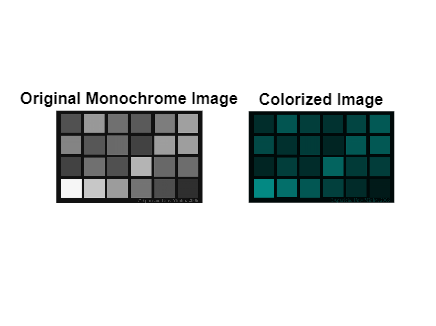

dt = datetime
   09-Jan-2025 16:03:33


filename = "colorized_images/colorized_image_20250109160348.png"

returned_img = 535×850×3 uint8 array
returned_img(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


returned_img = transformImage(c_redMatrix, c_greenMatrix, c_blueMatrix)

% Test if tinting the image is possible.
% b_redMatrix = [200 + zeros(1, 8)]'
% b_greenMatrix = [50 + zeros(1, 8)]'
% b_blueMatrix = [200 + zeros(1, 8)]'
% 
% c_redMatrix = lsqr(S_grayscaleMatrix, b_redMatrix)
% c_greenMatrix = lsqr(S_grayscaleMatrix, b_greenMatrix)
% c_blueMatrix = lsqr(S_grayscaleMatrix, b_blueMatrix)

% transformImage(c_redMatrix, c_greenMatrix, c_blueMatrix)

function rgbImage = transformImage(c_redMatrix, c_greenMatrix, c_blueMatrix)
% Read the monochrome image.
initial_rgbImage = imread('Reflective-color-chart-reference-COLOR.png', 'png');
grayImage = rgb2gray(initial_rgbImage);

% Define a color correction matrix for RGB color mapping.
% Simple example below.
colorCorrectionMatrix = [
    c_redMatrix'; % Red channel mapping
    c_greenMatrix'; % Green channel mapping
    c_blueMatrix'; % Blue channel mapping
    ]

% Get image dimensions.
[rows, cols] = size(grayImage);

% Initialize RGB image matrix.
% rgbImage = zeros(rows, cols, 3);
rgbImage = initial_rgbImage; % Hijacks format used by imread.

% Apply color correction by looping over each pixel.
for i = 1:rows
    for j = 1:cols
        % Get grayscale value of current pixel.
        grayValue = double(grayImage(i, j)); 

        % Apply color correction matrix to map grayscale value to RGB
        % values.
        rgbValue = colorCorrectionMatrix * [grayValue; grayValue; grayValue];
        
        % Store RBG values in the output image matrix.
        rgbImage(i, j, :) = uint8(rgbValue); % ':' is the rgb vector
    end
end

% Display the original monochrome image and the transformed color image.
figure;
subplot(1, 2, 1);
imshow(grayImage);
title('Original Monochrome Image');
% rgbImage

subplot(1, 2, 2);
imshow(rgbImage);
title('Colorized Image');

% Save the colorized image to a new file.
dt = datetime("now")
dt.Format = 'yyyyMMddHHmmSS';
filename = 'colorized_images/colorized_image_' + string(dt) + '.png'
imwrite(rgbImage, filename);

end